# Bayesian Learning

In this example, we illustrate Baysian Learning when the binomial distribution is the model distribution for a larger data set.  We will simulate the estimation of p when n is known.

Define the model distribution and the data set. Our data

D=[19 16 27 20 26 21 23 22 24 18 19 19 22 22 17 22 21 22 16 24 19 24 23 21 19 ...
    20 17 24 25 28 27 25 20 22 19 23 22 19 18 19 21 17 19 21 21 17 19 24 19 23]';

represents the number of preferred outcomes observed in 50 experiments involving

n=30;

independent Bernoulli trials each.

In addition, we will state the true value of $p$, or the probability of observing a preferred outcome in any given Bernoulli trial. Normally, we would not know this, but we'll use it here for demonstrating how well our estimate agrees with the true parameter value.

p_actual=0.7111;   %True value of p.  

Our goal is to estimate p by analyzing some or all of the data in D.  Our model distribution in this example is the binomial distribution.  We will choose a discrete prior distribution for describing possible representative values of p and iteratively use Bayesian Learning to update these prior probabilities with computed posterior probabilities.

Define the prior distribution.  Initially, we'll assume it is uniform.

intervals=50;
p=linspace(0,1,intervals+1); %Endpoints of subintervals that partition [0,1]
p=(p(2:end)+p(1:end-1))/2; %Compute the midpoints of each subinterval and use these as the representative values
%Example of Baysian Learning when the binomial distribution is the sampling
%distribution.  We will simulate the estimation of p when n is known.

prior=ones(1,length(p))*1.0/length(p); %Discrete prior distribution (uniform).

p_estimate=[];              % Empty array for storing successive point estimates to p_actual.
BL=[];
MLE=[];

Begin the Bayesian Learning iteration. This will produce a visualization that compares the performance of MLE and BL at estimating the true value of $p$ as we add data to our set of observations. 

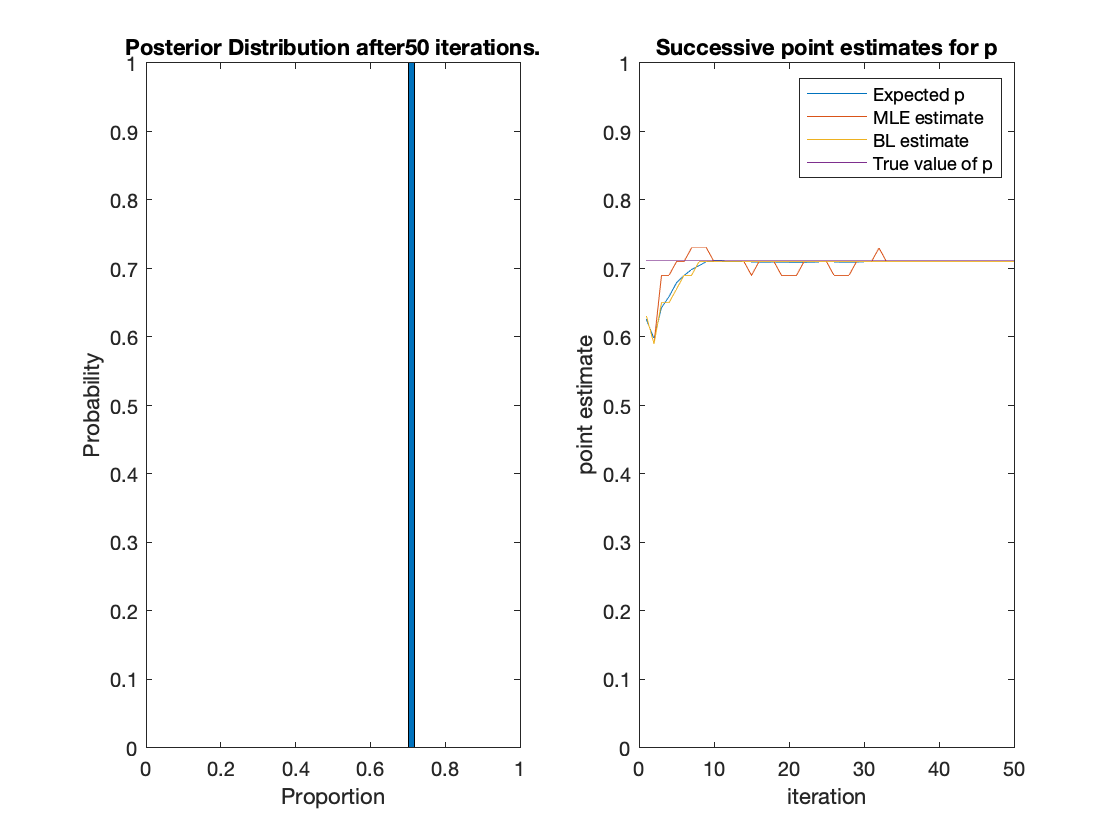

figure(1);
f=1;

for i=1:length(D)
    f=f.*binopdf(D(i),n,p);       % likelihood function
    [M,I]=max(f);
    MLE=[MLE,p(I)];      % MLE Estimate for p value
    
    TP=f*prior';            % Total (Marginal) probability of D
    posterior=f.*prior/TP;  % Prior probability
    [M,I]=max(posterior);
    BL=[BL,p(I)];                  %MAP estimate for p value
    
    prior=posterior;                    % Update the prior with the posterior
    
    p_estimate=[p_estimate, prior*p'];  %Expected p value
   
    subplot(1,2,1);         % begin visualizing posterior distribution
    bar(p,posterior);
    axis([0 1 0 1]);
    title(strcat('Posterior Distribution after  ',num2str(i),' iterations.'));
    xlabel('Proportion');
    ylabel('Probability');
    
    subplot(1,2,2);                     % Begin visualizing p estimates
    plot(1:i,p_estimate,1:i,MLE,1:i,BL,1:i,p_actual*ones(1,i));
    axis([0,length(D),0,1]);
    legend('Expected p', 'MLE estimate', 'BL estimate','True value of p');
    title('Successive point estimates for p');
    xlabel('iteration');
    ylabel('point estimate');
    pause(0.3);
end